# Phase plane!

N = 1000;
gamma = 0.20;
alpha = 0.02;

R0 = 1.5;

beta = R0*gamma/N;


Svalues = linspace(0,N,27);
Ivalues = linspace(0,0.45*N,23);

[Sgrid,Igrid] = meshgrid(Svalues,Ivalues);

Calculate R at every point:

Rgrid = N - Sgrid - Igrid;

Only the points where $R \ge 0$ are feasible.

feasible = (Rgrid >= 0)

feasible = 23×27 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0 

We already know the expressions for $S'$ and $I'$

dS = -beta*Sgrid.*Igrid + alpha*Rgrid;
dI =  beta*Sgrid.*Igrid - gamma*Igrid;

The vector $(S', I') gives us both direction and magnitude. But here we only want the magnitude at every combination of $(S, I)$

speed = sqrt(dS.^2 + dI.^2);

% Avoid division by zero at equilibrium points
speed(speed == 0) = 1;

dSplot = dS./speed;
dIplot = dI./speed;


% Do not draw arrows in physically impossible regions
dSplot(~feasible) = NaN;
dIplot(~feasible) = NaN;

We can plot this!

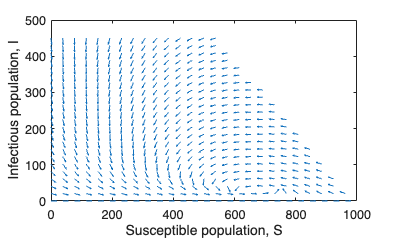

figure

quiver(Sgrid,Igrid,dSplot,dIplot,0.45)
ylim([0 500])
xlim([0 N])
xlabel('Susceptible population, S')
ylabel('Infectious population, I')

hold on

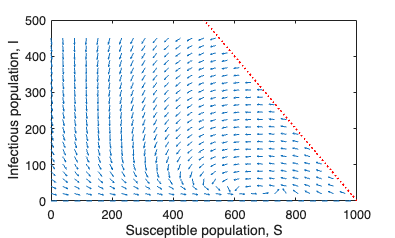

plot([0 N],[N 0],'r:','LineWidth',1.2)

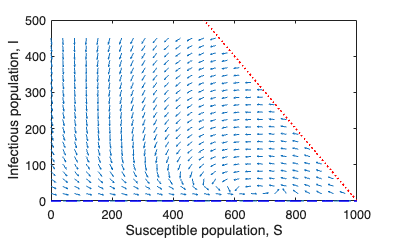


% ---------------------------------------------------------
% I = 0 nullcline
%
% I' = I*(beta*S - gamma)
%
% Therefore I' = 0 when I = 0.w
% ---------------------------------------------------------

plot([0 N],[0 0],'b--','LineWidth',1.2)

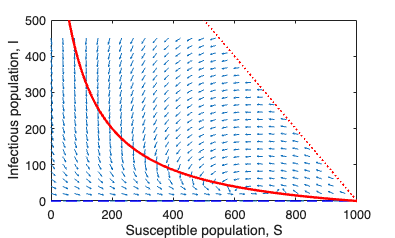

% ---------------------------------------------------------
% S' = 0 nullcline
%
% S' = -beta*S*I + alpha*(N-S-I)
%
% Setting S' = 0 gives:
%
% I = alpha*(N-S)/(alpha + beta*S)
% ---------------------------------------------------------

Snull = linspace(0,N,500);

InullS = alpha*(N-Snull) ./ ...
         (alpha + beta*Snull);

plot(Snull, InullS, 'r', 'LineWidth', 1.8)

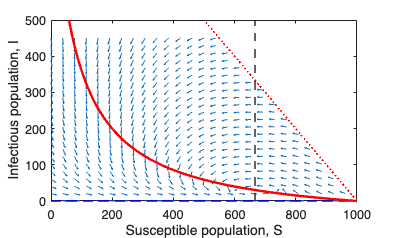


% ---------------------------------------------------------
% Second I' = 0 nullcline
%
% I' = I*(beta*S - gamma)
%
% For I > 0:
%
% beta*S - gamma = 0
%
% S = gamma/beta = N/R0
% ---------------------------------------------------------

Scrit = gamma/beta;

xline(Scrit,'--','LineWidth',1.5)

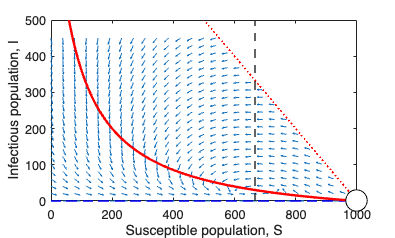


% ---------------------------------------------------------
% Disease-free equilibrium
%
% (S*,I*) = (N,0)
% ---------------------------------------------------------

plot(N,0,'ko', ...
    'MarkerFaceColor','w', ...
    'MarkerSize',16)

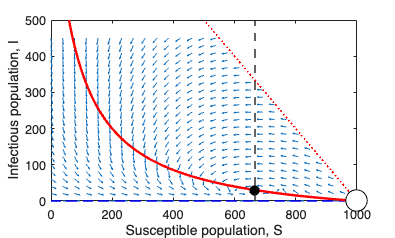


% ---------------------------------------------------------
% Endemic equilibrium
%
% Exists because R0 > 1
% ---------------------------------------------------------

Sstar = N/R0;

Istar = alpha*N/(alpha + gamma) * ...
        (1 - 1/R0);

plot(Sstar,Istar,'ko', ...
    'MarkerFaceColor','k', ...
    'MarkerSize',7)

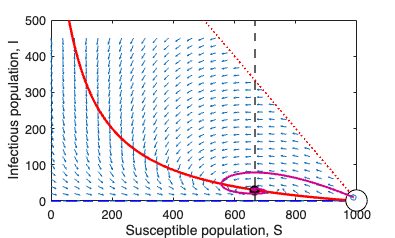


% ---------------------------------------------------------
% Plot a trajectory from one initial condition
% ---------------------------------------------------------

x0 = [990; 10];

[t,x] = ode45( ...
    @(t,x) SIRS_reduced_model( ...
        t,x,beta,gamma,alpha,N), ...
    [0 500], ...
    x0);

% x(:,1) = S(t)
% x(:,2) = I(t)

plot(x(:,1),x(:,2),'LineWidth',1.5)

% Mark the starting point
plot(x(1,1),x(1,2),'o','MarkerSize',4)




function dxdt = SIRS_reduced_model(~,x,beta,gamma,alpha,N)
S = x(1);
I = x(2);
R = N - S - I;

dSdt = -beta*S*I + alpha*R;
dIdt =  beta*S*I - gamma*I;

dxdt = [dSdt; dIdt];
end